## Test case 2

## ARM 1

L1 = Link('revolute','d',0, 'a',3,'alpha',pi/2);
L2 = Link('revolute','d',0, 'a',3,'alpha',pi/2);
L3 = Link('revolute','d',0, 'a',3,'alpha',0);
ARM1 = SerialLink([L1 L2 L3],'name','ARM 1');

## ARM 2

K1 = Link('revolute','d',0, 'a',3,'alpha',pi/2);
K2 = Link('revolute','d',0, 'a',3,'alpha',pi/2);
K3 = Link('revolute','d',0, 'a',3,'alpha',0);
ARM2 = SerialLink([K1 K2 K3],'name','ARM 2');

## Translating base

Ta = transl(6,0,0);
Tb = transl(-6,0,0);
ARM1.base = Ta;
ARM2.base = Tb;

## Initial pose

clf
T01 = transl(9,3,3)*rpy2tr(-0,0,-90);
T02 = transl(-9,3,3)*rpy2tr(-180,0,-90);
q01 = ARM1.ikine(T01,'q0',[pi/2 pi/2 -pi/2],'mask',[1 1 1 0 0 0])

q01 =     1.5708    1.5708    1.5708


q02 = ARM2.ikine(T02,'q0',[pi/2 pi/2 pi/2],'mask',[1 1 1 0 0 0])

q02 =     1.5708    1.5708   -1.5708


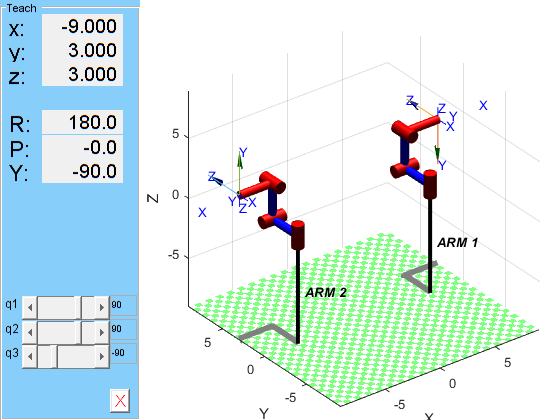

ARM1.teach(q01)
hold on 
ARM2.teach(q02)
trplot(T01)
hold on
trplot(T02)

## Object transfer

clf
T1 = transl(-0.022,6.688, 0)*rpy2tr(-132.0,0,-180)

T1 =    -1.0000         0         0   -0.0220
         0    0.6691   -0.7431    6.6880
         0   -0.7431   -0.6691         0
         0         0         0    1.0000


q1 = ARM1.ikine(T1,'q0',[2 2 2],'mask',[1 1 1 0 0 0])

q1 =     2.3100   -0.0000    0.0185


q2 = ARM2.ikine(T1,'q0',[0 0 0],'mask',[1 1 1 0 0 0])

q2 =     0.7840    0.0000   -0.1725


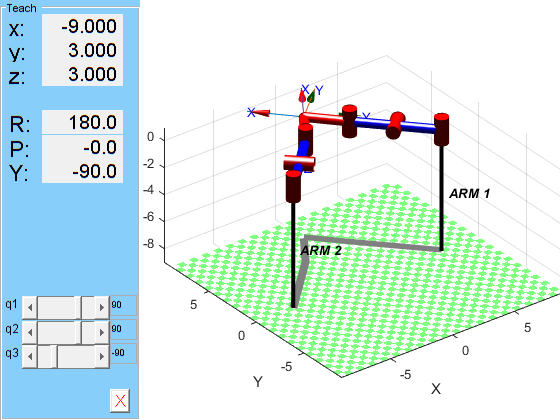

tg1 = jtraj(q01,q1,50);
tg2 = jtraj(q02,q2,50);
tg3 = jtraj(q2,q02,50);
tg4 = jtraj(q1,q01,50);
ARM1.teach(q01)
hold on
ARM2.teach(q02)
hold on
axis equal
ARM1.plot(tg1)
hold on
ARM2.plot(tg2)

## Return to initial pose

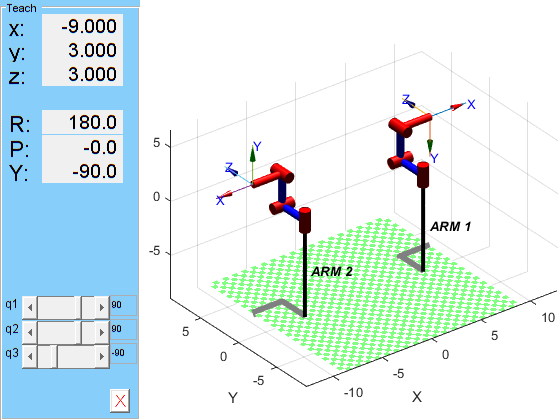

hold on 
ARM1.plot(tg4)
hold on 
ARM2.plot(tg3)